Problema 1:

clc;
clear;

f = @(x) x^2 - 4;      % Function
df = @(x) 2*x;         % Derivative for Newton-Raphson
tol = 1e-6;            % Tolerance
max_iter = 100;        % Maximum iterations

% Newton-Raphson Method
x = 1.5;  
for i = 1:max_iter
    x_new = x - f(x)/df(x);
    if abs(x_new - x) < tol
        break;
    end
    x = x_new;
end
fprintf('Newton-Raphson: root = %.2f in %d iterations\n', x, i);

Newton-Raphson: root = 2.00 in 4 iterations



% Bisection Method
a = 0; b = 3;  % Initial interval
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection: root = %.2f in %d iterations\n', c, j);

Bisection: root = 2.00 in 22 iterations


En este problema el metodo de Newton-Raphson lo hace en menor interaciones por lo que podemos concluir que es más rápido

Problema 2:

clc;
clear;

f = @(x) (x - 1).*(x - 2).*(x - 3);          % Function
df = @(x) 3*x.^2 - 12*x + 11;               % Derivative for Newton-Raphson
tol = 1e-6;
max_iter = 100;

%% Newton-Raphson Method for three initial guesses
initial_guesses = [0.5, 2.5, 3.5];

for k = 1:length(initial_guesses)
    x = initial_guesses(k);
    for i = 1:max_iter
        x_new = x - f(x)/df(x);
        if abs(x_new - x) < tol
            break;
        end
        x = x_new;
    end
    fprintf('Newton-Raphson (x0 = %.1f): root = %.6f in %d iterations\n', ...
            initial_guesses(k), x, i);
end

Newton-Raphson (x0 = 0.5): root = 1.000000 in 6 iterations
Newton-Raphson (x0 = 2.5): root = 1.000000 in 2 iterations
Newton-Raphson (x0 = 3.5): root = 3.000000 in 6 iterations



%% Bisection Method for three intervals
intervals = [0, 1.5; 1.5, 2.5; 2.5, 3.5];

for k = 1:size(intervals, 1)
    a = intervals(k,1);
    b = intervals(k,2);
    for j = 1:max_iter
        c = (a + b)/2;
        if abs(f(c)) < tol || abs(b - a)/2 < tol
            break;
        end
        if f(a)*f(c) < 0
            b = c;
        else
            a = c;
        end
    end
    fprintf('Bisection [%g, %g]: root = %.6f in %d iterations\n', ...
            intervals(k,1), intervals(k,2), c, j);
end

Bisection [0, 1.5]: root = 1.000000 in 20 iterations
Bisection [1.5, 2.5]: root = 2.000000 in 1 iterations
Bisection [2.5, 3.5]: root = 3.000000 in 1 iterations


En este segundo problema, Newton-Raphson encontró raíces diferentes según el punto inicial; Bisection siempre encuentra la raíz correcta en cada intervalo.

Problema 3:

% problem3_root_finding.m
% Root finding for f(x) = x^3 using Newton-Raphson and Bisection

clc;
clear;

f = @(x) x^3;       % Function
df = @(x) 3*x^2;    % Derivative
tol = 1e-6;
max_iter = 100;

%% Newton-Raphson
x = 0.1;
for i = 1:max_iter
    if df(x) == 0
        break;
    end
    x_new = x - f(x)/df(x);
    if abs(x_new - x) < tol
        break;
    end
    x = x_new;
end
fprintf('Newton-Raphson: root = %.6f in %d iterations\n', x, i);

Newton-Raphson: root = 0.000003 in 27 iterations



%% Bisection
a = -1; b = 1;
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection: root = %.6f in %d iterations\n', c, j);

Bisection: root = 0.000000 in 1 iterations


En este problema Newton-Raphson converge muy lento o falla, mientras que Bisection funciona bien.

Problema 4:

clc;
clear;

f = @(x) abs(x);    % Non-differentiable function
% No derivative because f is not differentiable at x = 0

tol = 1e-6;
max_iter = 100;

%% Newton-Raphson (will fail)
x = 0;  % Initial guess at the non-differentiable point
fprintf('Newton-Raphson: fails because derivative is undefined at x = %.1f\n', x);

Newton-Raphson: fails because derivative is undefined at x = 0.0



%% Bisection Method
a = -1; b = 1;

for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    % f(x) = |x|, so f(a)*f(c) is always >= 0 unless c crosses 0
    if c < 0
        a = c;
    else
        b = c;
    end
end
fprintf('Bisection: root = %.6f in %d iterations\n', c, j);

Bisection: root = 0.000000 in 1 iterations


En este problema 4, Newton-Raphson no funciona pero Bisection encuentra la raíz sin problema.

Problema 5:

clc;
clear;

f = @(x) cos(x) - x;      % Oscillating function
df = @(x) -sin(x) - 1;     % Derivative

tol = 1e-6;
max_iter = 100;

%% Newton-Raphson
x = 1;  % Initial guess
for i = 1:max_iter
    x_new = x - f(x)/df(x);
    if abs(x_new - x) < tol
        break;
    end
    x = x_new;
end
fprintf('Newton-Raphson: root = %.6f in %d iterations\n', x, i);

Newton-Raphson: root = 0.739085 in 4 iterations



%% Bisection
a = 0; b = 1;
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection: root = %.6f in %d iterations\n', c, j);

Bisection: root = 0.739085 in 20 iterations


En este problema los dos métodos convergen, pero Newton-Raphson es más rápido.

Problema 6: (Poor Initial Guess)

clc;
clear;

f = @(x) x^3 - x - 1;       % Function
df = @(x) 3*x^2 - 1;        % Derivative

tol = 1e-6;
max_iter = 100;

%% Newton-Raphson
x = 0;  % Poor initial guess
for i = 1:max_iter
    if df(x) == 0
        fprintf('Newton-Raphson: derivative zero, stopping at iteration %d\n', i);
        break;
    end
    x_new = x - f(x)/df(x);
    if abs(x_new - x) < tol
        x = x_new;
        break;
    end
    x = x_new;
end
fprintf('Newton-Raphson: root = %.6f in %d iterations (x0 = 0)\n', x, i);

Newton-Raphson: root = 1.324718 in 21 iterations (x0 = 0)



%% Bisection
a = 1; b = 2;
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection: root = %.6f in %d iterations\n', c, j);

Bisection: root = 1.324718 in 20 iterations


 7:

Problem 8:

clc;
clear;

% Define the function and its derivative
f = @(x) 1./x.^2 - 2./((x-1).^2);  % Function to find the root
df = @(x) -2./x.^3 + 4./((x-1).^3); % Derivative for Newton-Raphson

tol = 1e-6;         % Tolerance
max_iter = 100;     % Maximum iterations

%% Newton-Raphson Method
x = -1;  % Initial guess
for i = 1:max_iter
    x_new = x - f(x)/df(x);
    if abs(x_new - x) < tol
        break;
    end
    x = x_new;
end
fprintf('Newton-Raphson: equilibrium point at x = %.6f in %d iterations\n', x, i);

Newton-Raphson: equilibrium point at x = -2.414214 in 8 iterations



%% Bisection Method
a = -3; b = -0.1;  % Initial interval
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection: equilibrium point at x = %.6f in %d iterations\n', c, j);

Bisection: equilibrium point at x = -2.414212 in 15 iterations



%% Result verification
k = 8.99e9;  % Coulomb constant
q1 = 1e-6;   % +1 μC
q2 = -2e-6;  % -2 μC
x_eq = x;    % Use Newton-Raphson result

% Electric field components
E1 = k*q1/x_eq^2;
E2 = k*q2/(x_eq-1)^2;
E_net = E1 + E2;

fprintf('\nElectric field verification:\n');


Electric field verification:


fprintf('E1 = %.6e N/C\n', E1);

E1 = 1.542440e+03 N/C


fprintf('E2 = %.6e N/C\n', E2);

E2 = -1.542440e+03 N/C


fprintf('Net E = %.6e N/C\n', E_net);

Net E = 9.158164e-06 N/C



% Plot the function for visualization
figure;
x_plot = linspace(-5, -0.1, 1000);
y_plot = 1./(x_plot.^2) - 2./((x_plot-1).^2);
plot(x_plot, y_plot);
hold on;
plot([x_eq x_eq], [min(y_plot) max(y_plot)], 'r--');
plot([-5 0], [0 0], 'k--');
grid on;
title('Function f(x) = 1/x^2 - 2/(x-1)^2');
xlabel('x');
ylabel('f(x)');
legend('f(x)', 'Equilibrium point');

Problem 9:

clc;
clear;

% Define the function and its derivative
f = @(x) 3./x.^2 - 1./(x-2).^2;                          % Function for root finding
df = @(x) -6./x.^3 + 2./(x-2).^3;                        % Derivative for Newton-Raphson

tol = 1e-6;                                              % Tolerance
max_iter = 100;                                          % Maximum iterations

%% Newton-Raphson Method (left root, x < 0)
x_left = -1;                                             % Initial guess (left side)
for i = 1:max_iter
    x_new = x_left - f(x_left)/df(x_left);
    if abs(x_new - x_left) < tol
        break;
    end
    x_left = x_new;
end
fprintf('Newton-Raphson (left): equilibrium at x = %.6f in %d iterations\n', x_left, i);

Newton-Raphson (left): equilibrium at x = -348183673131879680.000000 in 100 iterations



%% Newton-Raphson Method (right root, x > 2)
x_right = 3;                                             % Initial guess (right side)
for i = 1:max_iter
    x_new = x_right - f(x_right)/df(x_right);
    if abs(x_new - x_right) < tol
        break;
    end
    x_right = x_new;
end
fprintf('Newton-Raphson (right): equilibrium at x = %.6f in %d iterations\n', x_right, i);

Newton-Raphson (right): equilibrium at x = 4.732051 in 8 iterations



%% Bisection Method (left root, x < 0)
a = -5; b = -0.1;                                        % Interval for left root
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection (left): equilibrium at x = %.6f in %d iterations\n', c, j);

Bisection (left): equilibrium at x = -0.100001 in 23 iterations



%% Bisection Method (right root, x > 2)
a2 = 2.1; b2 = 5;                                        % Interval for right root
for j = 1:max_iter
    c2 = (a2 + b2)/2;
    if abs(f(c2)) < tol || abs(b2 - a2)/2 < tol
        break;
    end
    if f(a2)*f(c2) < 0
        b2 = c2;
    else
        a2 = c2;
    end
end
fprintf('Bisection (right): equilibrium at x = %.6f in %d iterations\n', c2, j);

Bisection (right): equilibrium at x = 4.732063 in 16 iterations


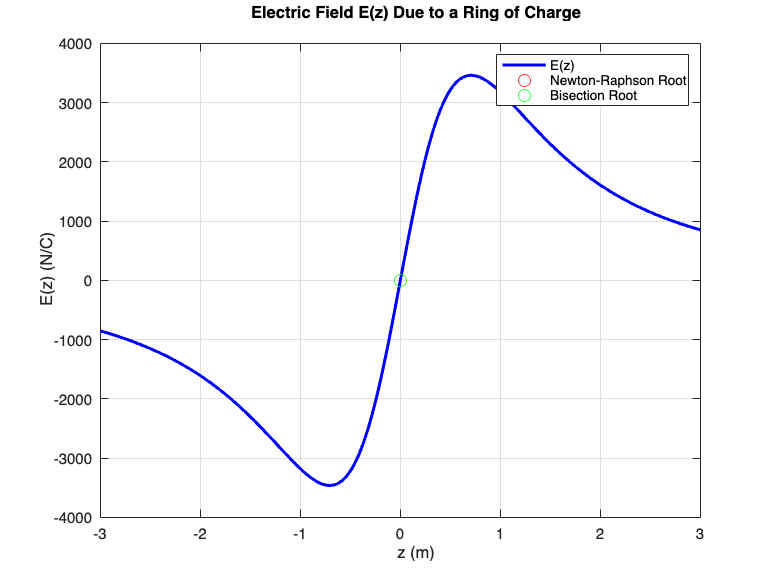


%% Plot the function
x1 = linspace(-5, 1.9, 500);
x2 = linspace(2.1, 5, 500);
y1 = f(x1);
y2 = f(x2);

figure;
plot(x1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(x2, y2, 'g', 'LineWidth', 1.5);
plot([x_left x_left], [min([y1 y2]) max([y1 y2])], 'r--');
plot([x_right x_right], [min([y1 y2]) max([y1 y2])], 'm--');
plot([-5 5], [0 0], 'k:');
xlabel('x');
ylabel('f(x)');
title('f(x) = 3/x^2 - 1/(x-2)^2');
legend('f(x) (x < 2)', 'f(x) (x > 2)', 'Left equilibrium', 'Right equilibrium', 'Location', 'Best');
grid on;
hold off;

Problem 10:

% Problem 10: Three-Charge System
% Find the point(s) along the x-axis (excluding regions between charges)
% where the net electric field is zero for:
% q1 = +1 μC at x = -1, q2 = -1 μC at x = 0, q3 = +1 μC at x = 1

clc;
clear;

% Define the function and its derivative
f = @(x) 1./(x+1).^2 - 1./x.^2 + 1./(x-1).^2;
df = @(x) -2./(x+1).^3 + 2./x.^3 - 2./(x-1).^3;

tol = 1e-6;         % Tolerance
max_iter = 100;     % Maximum iterations

% Plot the function to identify approximate roots
x_plot = linspace(-4, -1.1, 500);
x_plot2 = linspace(1.1, 4, 500);
y_plot = f(x_plot);
y_plot2 = f(x_plot2);

figure;
plot(x_plot, y_plot, 'b', 'LineWidth', 1.5); hold on;
plot(x_plot2, y_plot2, 'g', 'LineWidth', 1.5);
plot([-4 4], [0 0], 'k--');
xlabel('x');
ylabel('f(x)');
title('f(x) = 1/(x+1)^2 - 1/x^2 + 1/(x-1)^2');
legend('f(x) (x < -1)', 'f(x) (x > 1)', 'E = 0');
grid on;

%% Newton-Raphson Method (left region, x < -1)
x_left = -2;  % Initial guess (left of all charges)
for i = 1:max_iter
    x_new = x_left - f(x_left)/df(x_left);
    if abs(x_new - x_left) < tol
        break;
    end
    x_left = x_new;
end
fprintf('Newton-Raphson (left): equilibrium at x = %.6f in %d iterations\n', x_left, i);

Newton-Raphson (left): equilibrium at x = -428219673350112000.000000 in 100 iterations



%% Newton-Raphson Method (right region, x > 1)
x_right = 2;  % Initial guess (right of all charges)
for i = 1:max_iter
    x_new = x_right - f(x_right)/df(x_right);
    if abs(x_new - x_right) < tol
        break;
    end
    x_right = x_new;
end
fprintf('Newton-Raphson (right): equilibrium at x = %.6f in %d iterations\n', x_right, i);

Newton-Raphson (right): equilibrium at x = 428219673350112000.000000 in 100 iterations



%% Bisection Method (left region, x < -1)
a = -4; b = -1.1;
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection (left): equilibrium at x = %.6f in %d iterations\n', c, j);

Bisection (left): equilibrium at x = -1.100001 in 22 iterations



%% Bisection Method (right region, x > 1)
a2 = 1.1; b2 = 4;
for j = 1:max_iter
    c2 = (a2 + b2)/2;
    if abs(f(c2)) < tol || abs(b2 - a2)/2 < tol
        break;
    end
    if f(a2)*f(c2) < 0
        b2 = c2;
    else
        a2 = c2;
    end
end
fprintf('Bisection (right): equilibrium at x = %.6f in %d iterations\n', c2, j);

Bisection (right): equilibrium at x = 3.999999 in 22 iterations



% Mark equilibrium points on the plot
plot([x_left x_left], [min([y_plot y_plot2]) max([y_plot y_plot2])], 'r--');
plot([x_right x_right], [min([y_plot y_plot2]) max([y_plot y_plot2])], 'm--');
legend('f(x) (x < -1)', 'f(x) (x > 1)', 'E = 0', 'Left equilibrium', 'Right equilibrium', 'Location', 'Best');
hold off;

Problema 11:

% Problem 11: Electric Field Due to a Ring of Charge (Approximate Root)
% Find the point along the z-axis where the electric field equals a given value E0

clc;
clear;

% Constants
k = 8.99e9;          % Coulomb constant (N m^2/C^2)
Q = 1e-6;            % Charge in Coulombs
R = 1;               % Radius in meters
E0 = 5;              % Given electric field value (N/C)

tol = 1e-6;          % Tolerance
max_iter = 100;      % Maximum iterations

% Define the function and its derivative
f = @(z) (k*Q*z)./((z.^2 + R^2).^(3/2)) - E0;
df = @(z) k*Q*((R^2 - 2*z.^2)./((z.^2 + R^2).^(5/2)));

% Newton-Raphson Method
z = 0.5;  % Initial guess
for i = 1:max_iter
    z_new = z - f(z)/df(z);
    if abs(z_new - z) < tol
        break;
    end
    z = z_new;
end
fprintf('Newton-Raphson: root = %.6f m in %d iterations\n', z, i);

Newton-Raphson: root = NaN m in 100 iterations



% Bisection Method
a = 0; b = 2;  % Interval where function changes sign
if f(a)*f(b) > 0
    error('Function does not change sign in [0,2], choose another interval');
end

for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection: root = %.6f m in %d iterations\n', c, j);

Bisection: root = 0.000556 m in 21 iterations



% Plot E(z) to visualize behavior
z_vals = linspace(-3, 3, 500);
E_vals = (k*Q*z_vals)./((z_vals.^2 + R^2).^(3/2));

figure;
plot(z_vals, E_vals, 'b-', 'LineWidth', 2);
hold on;
plot(z, E0, 'ro', 'MarkerSize', 8, 'DisplayName', 'Newton-Raphson Root');
plot(c, E0, 'go', 'MarkerSize', 8, 'DisplayName', 'Bisection Root');
xlabel('z (m)');
ylabel('E(z) (N/C)');
title('Electric Field E(z) Due to a Ring of Charge');
grid on;
legend('E(z)', 'Newton-Raphson Root', 'Bisection Root');
hold off;

Problem 12:

% Problem 12: Electric Potential Zero Point
% Two charges: q1 = +1 μC at x = 0, q2 = -2 μC at x = 1
% Find the point(s) where the electric potential is zero (scalar sum).

clc;
clear;

% Define the potential function and its derivative, handling absolute values
f = @(x) 1./abs(x) - 2./abs(x-1);
df = @(x) -1./(abs(x).^2).*sign(x) + 2./(abs(x-1).^2).*sign(x-1);

tol = 1e-6;         % Tolerance
max_iter = 100;     % Maximum iterations

% --- Find root to the left of both charges (x < 0) ---

%% Newton-Raphson Method (x < 0)
x_left = -1;  % Initial guess
for i = 1:max_iter
    x_new = x_left - f(x_left)/df(x_left);
    if abs(x_new - x_left) < tol
        break;
    end
    x_left = x_new;
end
fprintf('Newton-Raphson (left): zero potential at x = %.6f in %d iterations\n', x_left, i);

Newton-Raphson (left): zero potential at x = -1.000000 in 1 iterations



%% Bisection Method (x < 0)
a = -5; b = -0.01;  % Avoid x = 0 (singularity)
for j = 1:max_iter
    c = (a + b)/2;
    if abs(f(c)) < tol || abs(b - a)/2 < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end
fprintf('Bisection (left): zero potential at x = %.6f in %d iterations\n', c, j);

Bisection (left): zero potential at x = -0.999999 in 19 iterations



% --- Find root to the right of both charges (x > 1) ---

%% Newton-Raphson Method (x > 1)
x_right = 2;  % Initial guess
for i = 1:max_iter
    x_new = x_right - f(x_right)/df(x_right);
    if abs(x_new - x_right) < tol
        break;
    end
    x_right = x_new;
end
fprintf('Newton-Raphson (right): zero potential at x = %.6f in %d iterations\n', x_right, i);

Newton-Raphson (right): zero potential at x = 911375649207342046272674594816.000000 in 100 iterations



%% Bisection Method (x > 1)
a2 = 1.01; b2 = 5;  % Avoid x = 1 (singularity)
for j = 1:max_iter
    c2 = (a2 + b2)/2;
    if abs(f(c2)) < tol || abs(b2 - a2)/2 < tol
        break;
    end
    if f(a2)*f(c2) < 0
        b2 = c2;
    else
        a2 = c2;
    end
end
fprintf('Bisection (right): zero potential at x = %.6f in %d iterations\n', c2, j);

Bisection (right): zero potential at x = 4.999999 in 22 iterations


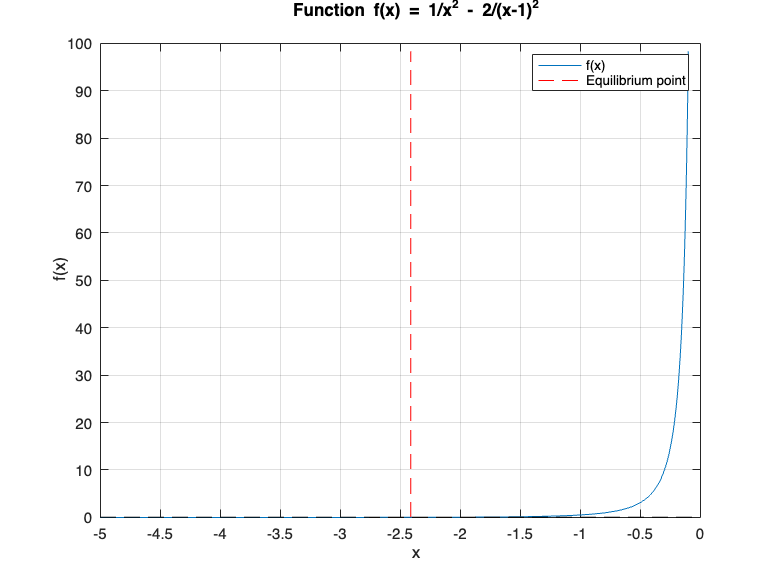


% --- Plot the potential function for visualization ---
x1 = linspace(-5, -0.01, 500);
x2 = linspace(1.01, 5, 500);
y1 = f(x1);
y2 = f(x2);

figure;
plot(x1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(x2, y2, 'g', 'LineWidth', 1.5);
plot([x_left x_left], [min([y1 y2]) max([y1 y2])], 'r--');
plot([x_right x_right], [min([y1 y2]) max([y1 y2])], 'm--');
plot([-5 5], [0 0], 'k:');
xlabel('x');
ylabel('f(x)');
title('f(x) = 1/|x| - 2/|x-1|');
legend('f(x) (x < 0)', 'f(x) (x > 1)', 'Left zero', 'Right zero', 'Location', 'Best');
grid on;
hold off;